# Stima OLS: modello costante

Richiamiamo le formule fondamentali nel metodo OLS.

**Relazioni fondamentali:**

$x$ segnale vero

$x=A\theta \;$segnale vero espresso in funzione di:

$A$ matrice dei regressori (delle funzioni base)

$\theta \;$ vettore dei parametri veri

**Matrici fondamentali:**

$Q={\left(A^T A\right)}^{-1}$ matrice gramiana inversa di A

$C=QA^T =$${\left(A^T A\right)}^{-1} A^T$ matrice pseudoinversa sinistra di A

$P=\textrm{AC}={A\left(A^T A\right)}^{-1} A^T$ matrice proiezione

**Formule per la stima:**

$e$ vettore degli errori di misura

$y=x+e$ segnale misurato

$\hat{\theta} =\textrm{Cy}$ parametri stimati

$\hat{x\;} =A\hat{\theta \;} =\textrm{Py}$ segnale stimato

**Formule per l'incertezza standard in ingresso (segnale misurato **$y$**)**

$u$ vettore delle incertezze standard

$R$ matrice dei coefficienti di correlazione

$\Sigma =\textrm{diag}\left(u\right)\;R\;\textrm{diag}\left(u\right)$ matrice covarianza, caso generale 

$\Sigma =\textrm{diag}\left(u\right){\;}^2$ matrice covarianza, caso di errori incorrelati

$\Sigma =u_0^2 I$ matrice covarianza, caso di errori omoschedastici ($u_0$= scalare, incertezza standard in ingresso)

**Formule per la propagazione dell'incertezza standard (parametri stimati **$\hat{\theta \;} \;$**)**

$\Sigma_{\theta } =C\Sigma C^T$ matrice covarianza di $\hat{\theta \;} \;$ (formula generale)

$\Sigma_{\theta } =u_0^2 \;Q$ matrice covarianza di $\hat{\theta \;} \;$ (caso di errori omoschedastici)

**Formule per la propagazione dell'incertezza standard (segnale stimato **$\hat{x\;} \;$**)**

$\Sigma_x =P\Sigma P^T$ matrice covarianza di $\hat{x} \;$ (formula generale)

$\Sigma_x =u_0^2 \ P$ matrice covarianza di $\hat{x} \;$ (caso di errori omoschedastici)

**Formule per l'estrazione dell'incertezza standard dalla matrice covarianza (parametri stimati **$\hat{\theta \;}$**)**

$u_{\theta \;} =\sqrt{\textrm{diag}\left(\Sigma_{\theta \;} \right)\;}$ incertezze standard dei parametri stimati

$R_{\theta \;} ={\textrm{diag}\left(u\right)}^{-1} \;\Sigma_{\theta \;} \;{\textrm{diag}\left(u\right)}^{-1}$ coeficienti di correlazione dei parametri stimati

Formule del tutto analoghe valgono per il segnale stimato $\hat{x\;}$.

**Formule per l'incertezza estesa (valutazione tipo B)**

$\textrm{cp}$ probabilità di copertura

$k_{\textrm{cp},B} =\Phi {\;}^{-1} \left(\frac{1+\textrm{cp}}{2}\right)=\textrm{norminv}\left(\frac{1+\textrm{cp}}{2}\right)$ fattore di copertura (valida per la valutazione di tipo B)

$U_{\textrm{cp},\theta \;} =k_{\textrm{cpB}} \;u_{\theta \;}$ incertezza estesa

$U_{\textrm{cp},x\;} =k_{\textrm{cp},B} \;u_{x\;}$ incertezza estesa segnale

**Formule per l'incertezza estesa (valutazione tipo A)**

$\textrm{cp}$ probabilità di copertura

$k_{\textrm{cp},A} ={F_t }^{-1} \left(\frac{1+\textrm{cp}}{2},\nu \;\right)=\textrm{tinv}\left(\frac{1+\textrm{cp}}{2},\nu \;\right)$ fattore di copertura (valida per la valutazione di tipo A)

$U_{\textrm{cp},\theta \;} =k_{\textrm{cp},A} \;u_{\theta \;}$ incertezza estesa parametri

$U_{\textrm{cp},x\;} =k_{\textrm{cp},A} \;u_{x\;}$ incertezza estesa segnale

**Formule per gli intervalli di confidenza**

$\theta_L =\hat{\theta} -U_{\textrm{cp},\theta \;}$ limite inferiore (lower) dell'intervallo

$\theta_U =\hat{\theta} +U_{\textrm{cp},\theta \;}$ limite superiore (upper) dell'intervallo

Formule del tutto analoghe valgono per il segnale stimato $\hat{x\;}$. Il risultato è un insieme di intervalli di confidenza dimensionalmente omogenei che vengono chiamati "banda di confidenza"

clear, rng('default')

## Creazione di istanti di tempo equispaziati nell'intervallo [0; Td[

% Dati
% N = 100; % numero di campioni (o di istanti)
% Td = 5; % durata dell'osservazione

% Domande
% Ts % periodo di campionamento
% n % vettore colonna degli indici dei campioni
% t % vettore colonna degli istanti di tempo (istanti di campionamento)

% Codice iniziale
N = 100; % numero di campioni (o di istanti)
Td = 5; % durata dell'osservazione

### Soluzione

Ts = Td/N

Ts = 0.0500

n = (0:N-1)'

n =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


t = n*Ts

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


## Creazione di errori di misura in ingresso omoschedastici, i.i.d. con distribuzione uniforme

% Dati
% U0 = 2 % scalare, incertezza di caso peggiore in ingresso

% Domande
% U % vettore delle incertezze di caso peggiore
% e % vettore colonna degli errori
% u0 % incertezza standard in ingresso
% u % vettore delle incertezze standard in ingresso
% R % matrice dei coefficienti di correlazione degli errori in ingresso
% Sigma % matrice covarianza degli errori in ingresso

% Codice iniziale
U0 = 2

U0 = 2

### Soluzione

U = U0*ones(N,1)

U =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


e = unifrnd(-U0,U0,[N,1]) %genera errori i.i.d. a distribuzione uniforme

e =     1.2589
    1.6232
   -1.4921
    1.6535
    0.5294
   -1.6098
   -0.8860
    0.1875
    1.8300
    1.8596


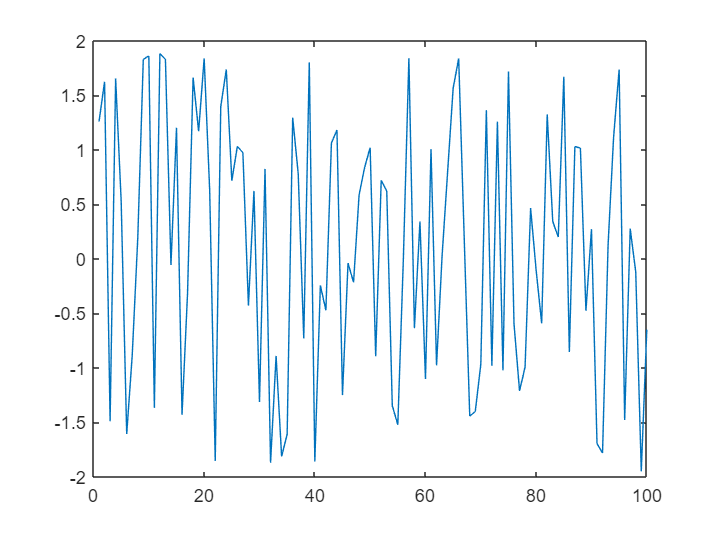

plot(e)

u0 = U0/sqrt(3)

u0 = 1.1547

u = U/sqrt(3)

u =     1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547


u = u0*ones(N,1)

u =     1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547
    1.1547


R = eye(N)

R =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0   

Sigma = diag(u)*R*diag(u) %formula generale

Sigma =     1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

Sigma = diag(u)^2 %formula per errori incorrelati

Sigma =     1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

Sigma = u0^2*eye(N) %formula per errori omoschedastici

Sigma =     1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3333         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

## Stima OLS per modello costante: x(t) = c0 

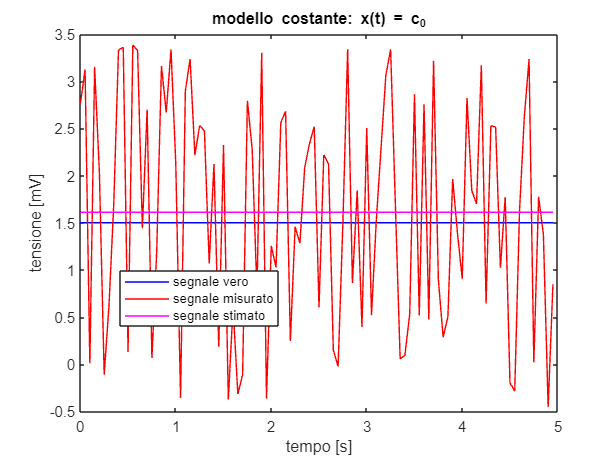

% Costruire anche una tabella e un grafico come in figura

% Dati
% c0 = 1.5 % valore vero del segnale
% e % vettore degli errori

% Domande
% theta % vettore dei parametri
% A % matrice delle funzioni base
% x % segnale vero
% y % segnale misurato
% Q % matrice gramiana inversa delle colonne di A
% C % matrice pseudoinversa sinistra di A
% P % matrice proiezione
% theta_hat % stima dei parametri sulla base di y
% x_hat % stima del segnale sulla base di y

% Codice iniziale
titolo = 'modello costante: x(t) = c_0'

titolo = 'modello costante: x(t) = c_0'

c0 = 1.5 % unico parametro del segnale

c0 = 1.5000

nomi_parametri = {'c_0'}

nomi_parametri = 1×1 cell array
    {'c_0'}


nome_segnale = 'tensione [mV]'

nome_segnale = 'tensione [mV]'

### Soluzione

#### Vettore theta e matrice A

theta = [c0]

theta = 1.5000

A = ones(N,1) %matrice dei regressori per il modello costante

A =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


#### Valori veri e misurati

x = A*theta

x =     1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000
    1.5000


y = x+e

y =     2.7589
    3.1232
    0.0079
    3.1535
    2.0294
   -0.1098
    0.6140
    1.6875
    3.3300
    3.3596


#### Matrici del metodo OLS

Q = (A'*A)^-1

Q = 0.0100

C = Q*A'

C =     0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100


P = A*C

P =     0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100
    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0

#### Stima parametri

theta_hat = C*y

theta_hat = 1.6120

theta_hat = mean(y) % formula immediata per il modello costante

theta_hat = 1.6120

table(theta,theta_hat,'RowNames',nomi_parametri)

ans = 1×2 table
           theta    theta_hat
           _____    _________

    c_0     1.5       1.612  


#### Stima segnale

x_hat = P*y

x_hat =     1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120


x_hat = A*theta_hat

x_hat =     1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120


x_hat = mean(y)*ones(N,1) % formula immediata per il modello costante

x_hat =     1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120
    1.6120


#### Grafico stima

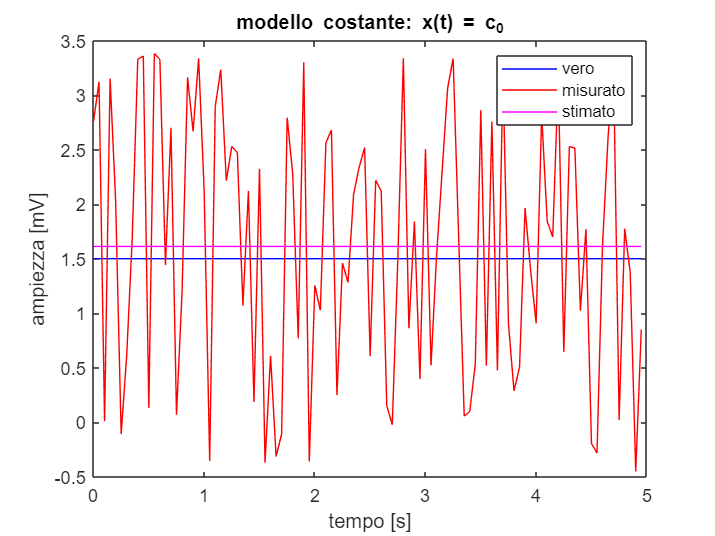

plot(t,x,'b',t,y,'r',t,x_hat,'m')
xlabel('tempo [s]')
ylabel('ampiezza [mV]')
legend('vero','misurato','stimato')
title('modello costante: x(t) = c_0')

## Valutazione di tipo B dell'incertezza sui parametri stimati

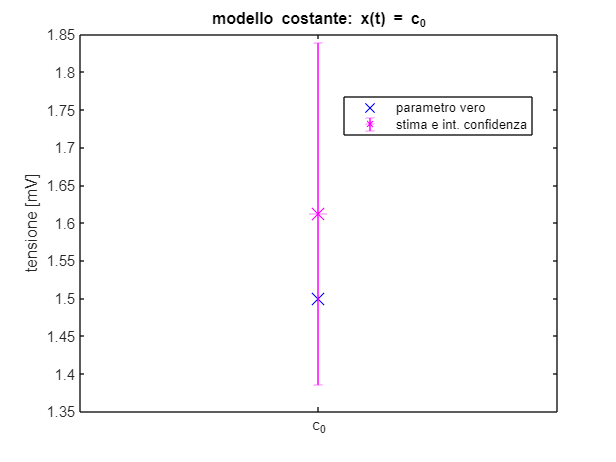

% Produrre anche un grafico come quello in figura

% Dati
% Quelli del quesito precedente
% cp % probabilità di copertura

% Domande
% Sigma_theta = matrice covarianza parametri stimati
% u_theta % vettore colonna incertezze standard parametri stimati
% kcp % fattore di copertura di tipo B
% Ucp_theta % vettore colonna incertezze estese di tipo B
% U_theta % vettore colonna incertezze di caso peggiore (di tipo B)
% kmax % fattore di copertura max - per verifica incertezze estese
% theta_L % limite "lower" dell'intervallo di confidenza
% theta_U % % limite "upper" dell'intervallo di confidenza

% Codice iniziale
cp = 0.95

cp = 0.9500

### Soluzione

#### Matrice covarianza, formula per errori omoschedastici

Sigma_theta = u0^2*Q

Sigma_theta = 0.0133

#### Matrice covarianza, formula generale 

Sigma_theta = C*Sigma*C'

Sigma_theta = 0.0133

#### Incertezze standard parametri

u_theta = sqrt(diag(Sigma_theta))

u_theta = 0.1155

#### Fattore di copertura di tipo B

kcp = norminv((1+cp)/2)

kcp = 1.9600

#### Incertezze estese parametri

Ucp_theta = u_theta*kcp

Ucp_theta = 0.2263

#### Incertezze di caso peggiore e fattore di copertura massimo

U_theta = abs(C)*U

U_theta = 2

kmax = U_theta/u_theta

kmax = 17.3205

#### Formule immediate per il modello costante (stima = media del segnale misurato) con errori omoschedastici

theta_hat = mean(y)

theta_hat = 1.6120

u_theta = u0/sqrt(N)

u_theta = 0.1155

U_theta = U0 %non significativa per N superiore a qualce unità

U_theta = 2

#### Intervalli di confidenza per i parametri

theta_L = theta_hat - Ucp_theta %lower

theta_L = 1.3857

theta_U = theta_hat + Ucp_theta %upper

theta_U = 1.8383

#### Grafico intervalli di confidenza

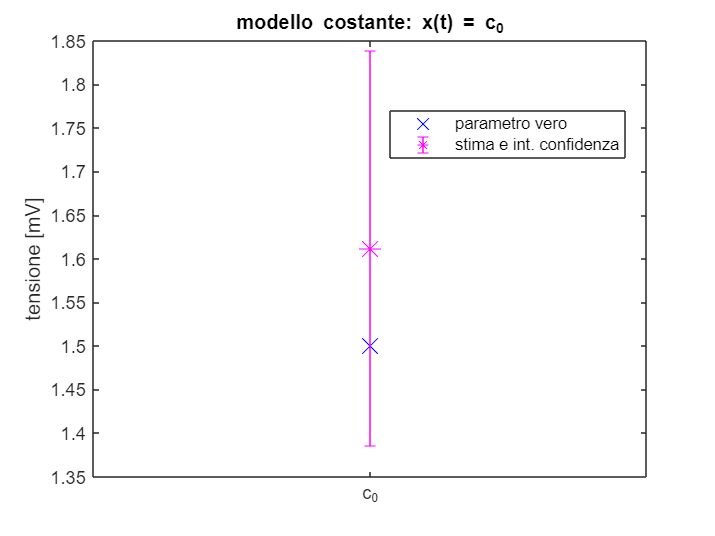

plot(theta,'bx','MarkerSize',12), hold on
errorbar(theta_hat,Ucp_theta,'m*','MarkerSize',12), hold off
ylabel(nome_segnale)
title(titolo)

xticks([1])
xticklabels({'c_0'})
legend('parametro vero','stima e int. confidenza','Location','best')

xlim([0.5,1.5])

## Valutazione di tipo A dell'incertezza sui parametri stimati 

(Stima di u0, per errori omoschedastici)

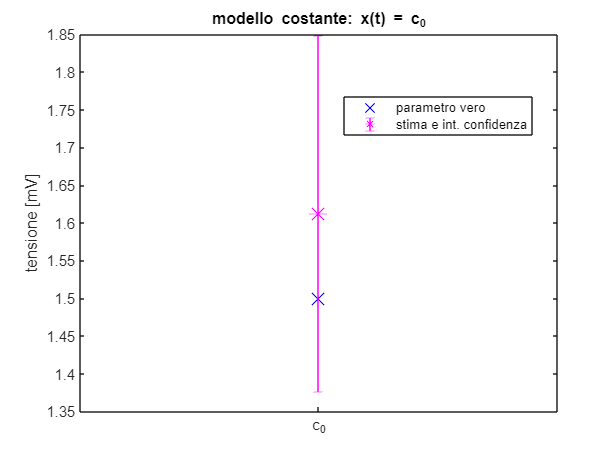

% Produrre anche un grafico come quello in figura

% Dati
% Quelli del quesito precedente
% cp % probabilità di copertura

% Domande
% e_hat % residuo
% nu % numero di g.d.l. del residuo
% u0_A % valutazione tipo A dell'incertezza in ingresso
% Sigma_theta_A = matrice covarianza parametri stimati
% u_theta_A % vettore colonna incertezze standard parametri stimati
% Ucp_theta_A % vettore colonna incertezze estese di tipo Aze estese
% theta_L_A % limite "lower" dell'intervallo di confidenza
% theta_U_A % % limite "upper" dell'intervallo di confidenza

% Codice iniziale
cp = 0.95

cp = 0.9500

### Soluzione

#### Residuo

e_hat = y - x_hat %residuo = stima dell'errore

e_hat =     1.1469
    1.5112
   -1.6040
    1.5415
    0.4175
   -1.7218
   -0.9980
    0.0755
    1.7180
    1.7476


#### Numero di g.d.l. del residuo

N_theta = size(A,2) %numero di colonne della matrice A

N_theta = 1

N_theta = numel(theta_hat) %numero di elementi del vettore theta_hat

N_theta = 1

nu = N - N_theta

nu = 99

#### Incertezza standard in ingresso

SSR = sum(e_hat.^2)

SSR = 139.7388

u0_A = sqrt(SSR/nu) %incertezza standard in ingresso, di tipo A con nu g.d.l

u0_A = 1.1881

#### Matrice covarianza parametri, formula per errori omoschedastici

Facciamo la valutazione tipo A nel solo caso di errori omoschedastici

Sigma_theta_A = u0_A^2*Q

Sigma_theta_A = 0.0141

#### Incertezze standard parametri

u_theta_A = sqrt(diag(Sigma_theta_A))

u_theta_A = 0.1188

#### Fattore di copertura di tipo A

kcp_A = tinv((1+cp)/2,nu)

kcp_A = 1.9842

#### Incertezza estesa parametri

Ucp_theta_A = u_theta_A*kcp_A

Ucp_theta_A = 0.2357

#### Formule immediate per il modello costante (stima = media del segnale misurato) con errori omoschedastici

u0_A = std(y)

u0_A = 1.1881

u0_A = sqrt(sum((y-mean(y)).^2)/(N-1)) %formula della deviazione standard (stima di Bessel non distorta)

u0_A = 1.1881

u_theta_A = u0_A/sqrt(N)

u_theta_A = 0.1188

#### Intervalli di confidenza per i parametri

theta_L_A = theta_hat - Ucp_theta_A

theta_L_A = 1.3762

theta_U_A = theta_hat + Ucp_theta_A

theta_U_A = 1.8477

#### Grafico intervalli di confidenza

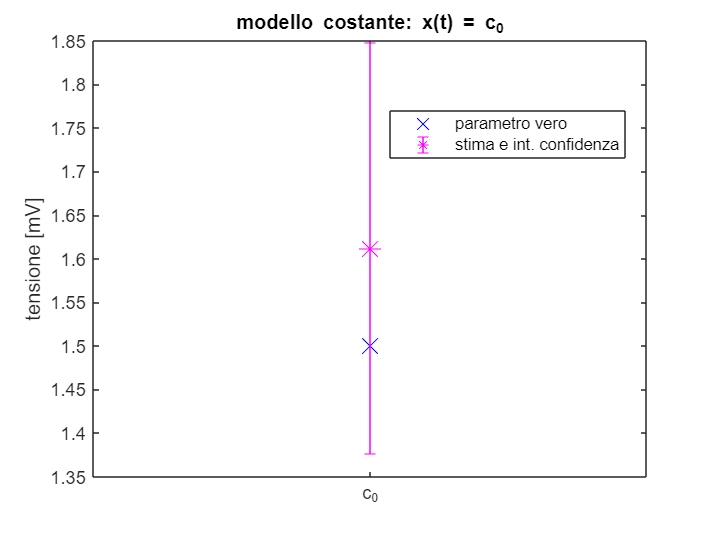

plot(theta,'bx','MarkerSize',12), hold on
errorbar(theta_hat,Ucp_theta_A,'m*','MarkerSize',12), hold off
ylabel(nome_segnale)
title(titolo)

xticks([1])
xticklabels({'c_0'})
legend('parametro vero','stima e int. confidenza','Location','best')

xlim([0.5,1.5])

## Valutazione di tipo B dell'incertezza sul segnale stimato

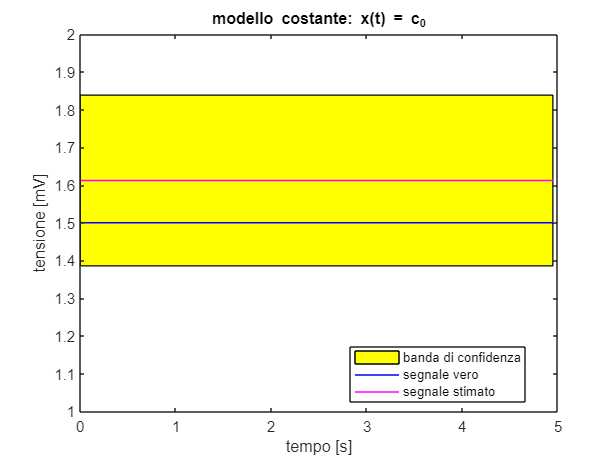

% Produrre anche un grafico come quello in figura

% Dati
% Quelli del quesito precedente

% Domande
% Sigma_x % matrice covarianza di x_hat
% u_x % vettore colonna incertezze standard segnale stimato
% R_x % matrice coefficienti di correlazione errori sul segnale stimato
% Ucp_x = % vettore colonna incertezze estese
% x_U % limite "lower" della banda di confidenza
% x_L % limite "upper" della banda di confidenza

### Soluzione

#### Matrice covarianza, formula per errori omoschedastici

Sigma_x = P*u0^2

Sigma_x =     0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133
    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.013

#### Matrice covarianza, formula generale 

Sigma_x = P*Sigma*P'

Sigma_x =     0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133
    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.0133    0.013

#### Incertezza segnale

u_x = sqrt(diag(Sigma_x))

u_x =     0.1155
    0.1155
    0.1155
    0.1155
    0.1155
    0.1155
    0.1155
    0.1155
    0.1155
    0.1155


Ucp_x = u_x*kcp

Ucp_x =     0.2263
    0.2263
    0.2263
    0.2263
    0.2263
    0.2263
    0.2263
    0.2263
    0.2263
    0.2263


#### Matrice dei coefficienti di correlazione

R_x = diag(u_x)^-1*Sigma_x*diag(u_x)^-1

R_x =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

#### Formule immediate per il modello costante (stima = media del segnale misurato) con errori omoschedastici

u_x = u0/sqrt(N)*ones(N,1)

u_x =     0.1155
    0.1155
    0.1155
    0.1155
    0.1155
    0.1155
    0.1155
    0.1155
    0.1155
    0.1155


R_x = ones(N,N)

R_x =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1 

#### Banda di confidenza per il segnale

x_U = x_hat + Ucp_x

x_U =     1.8383
    1.8383
    1.8383
    1.8383
    1.8383
    1.8383
    1.8383
    1.8383
    1.8383
    1.8383


x_L = x_hat - Ucp_x

x_L =     1.3857
    1.3857
    1.3857
    1.3857
    1.3857
    1.3857
    1.3857
    1.3857
    1.3857
    1.3857


#### Grafico banda di confidenza

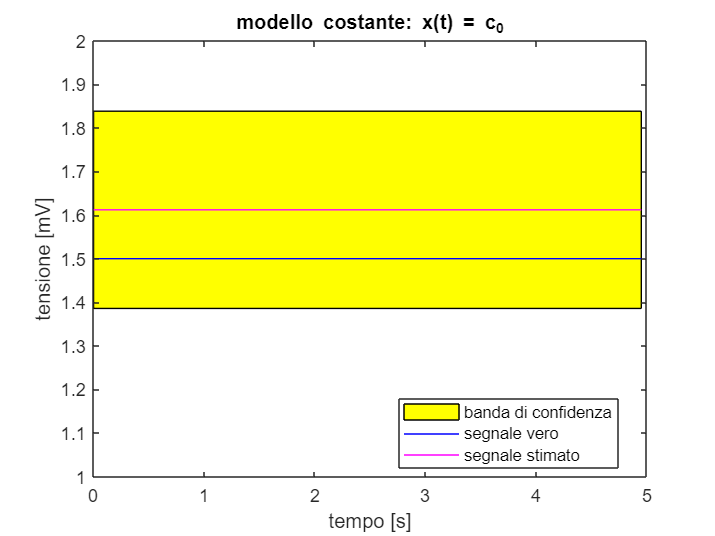

fill([t', fliplr(t')], [x_L', fliplr(x_U')], 'y')
hold on
plot(t,x,'b',t,x_hat,'m')
hold off
xlabel('tempo [s]')
ylabel(nome_segnale)
title(titolo)
legend('banda di confidenza','segnale vero','segnale stimato','Location','best')
ylim([1,2])